% Compute signal correlation across stimulus locations/angles
fGauss = @(x,a,b,c) a * exp( -(x - b).^2 / (2*c^2) );

% Neuron 1 - SEF                  Neuron 2 - FEF/SC
a1 = 1;  a2 = 3; %amplitude
b1 =4;  b2 =3; %shift
c1 =1.8;  c2 =1; %width

angDeg = 0 : 45 : 360;
angRad = deg2rad(angDeg);

actN1 = fGauss(angRad, a1,b1,c1);
actN2 = fGauss(angRad, a2,b2,c2);
[rhoSignal,pvalSignal] = corr(actN1',actN2', 'Type','Pearson', 'Tail','both')

rhoSignal = 0.6067

pvalSignal = 0.0832


% Compute noise correlation for single stimulus location
idxCheck = 5; %specified location/angle (starting from 0)
angCheck = angRad(idxCheck);
SIGMA =0.3; %SD of single-trial activation (N1 & N2)
RHO =-0.3; %simulated noise correlation between N1 & N2

nSamp = 100;
actRand = SIGMA * randn(nSamp,2);
actRand(:,2) = RHO*actRand(:,1) + sqrt(1-RHO^2)*actRand(:,2);
[rhoNoise,pvalNoise] = corr(actRand(:,1),actRand(:,2), 'Type','Pearson', 'Tail','both')

rhoNoise = -0.2155

pvalNoise = 0.0313

Plot neuron activation

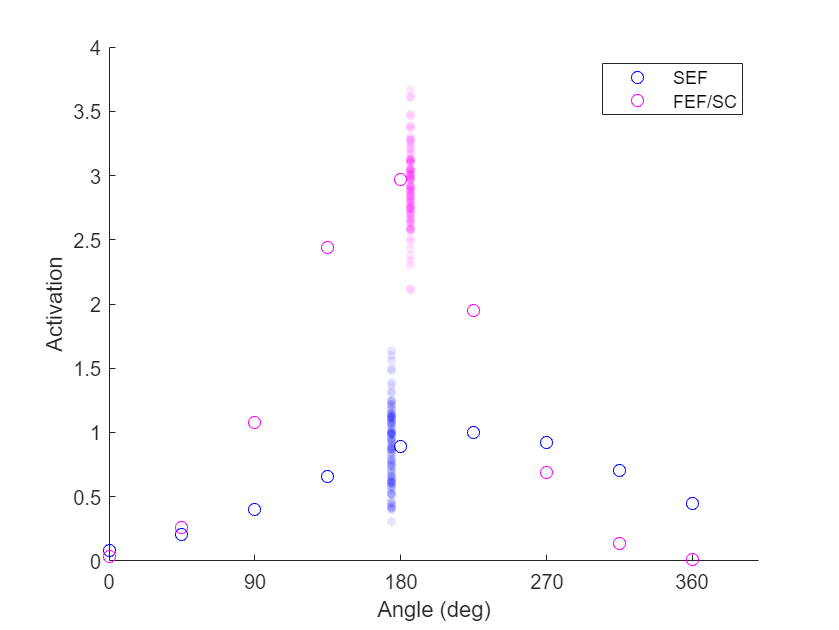

hfAct = figure(); hold on
hpN1 = plot(angRad,actN1, 'bo');
hpN2 = plot(angRad,actN2, 'mo');
scatter(angCheck-0.1,actN1(idxCheck)+actRand(:,1), 20,'b','filled', 'MarkerFaceAlpha',0.1)
scatter(angCheck+0.1,actN2(idxCheck)+actRand(:,2), 20,'m','filled', 'MarkerFaceAlpha',0.1)
xlabel('Angle (deg)'); xticks(angRad(1:2:end)); xticklabels(num2cell(angDeg(1:2:end)))
ylabel('Activation')
legend({'SEF','FEF/SC','',''})

Plot signal correlation

hfCorr = figure();
subplot(1,2,1); hold on; title('Signal correlation')
scatter(actN1,actN2, 40,'k','filled', 'MarkerFaceAlpha',0.5)
axis square
xlabel('Neuron 1 activation')
ylabel('Neuron 2 activation')

Plot noise correlation

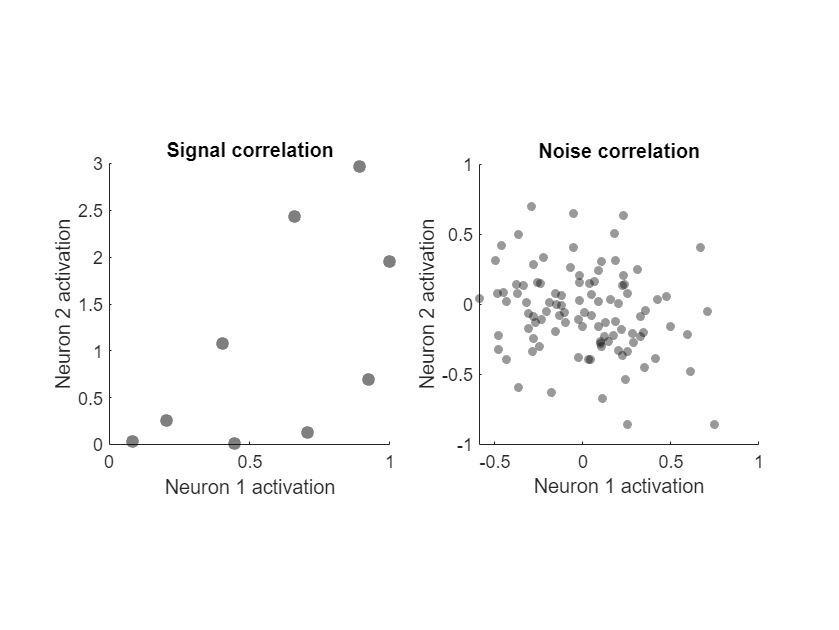

subplot(1,2,2); hold on; title('Noise correlation')
scatter(actRand(:,1),actRand(:,2), 20,'k','filled', 'MarkerFaceAlpha',0.4)
axis square
xlabel('Neuron 1 activation')
ylabel('Neuron 2 activation')